# **LABORATORIO 1 ROBOTICA**

**UNIVERSIDAD NACIONAL DE COLOMBIA**

**Aristides Daniel Cantero Castillo**

**Farid Alexis Estepa Quintero **

**William Andrés Castillo Bautista**

**a) Figura robot**

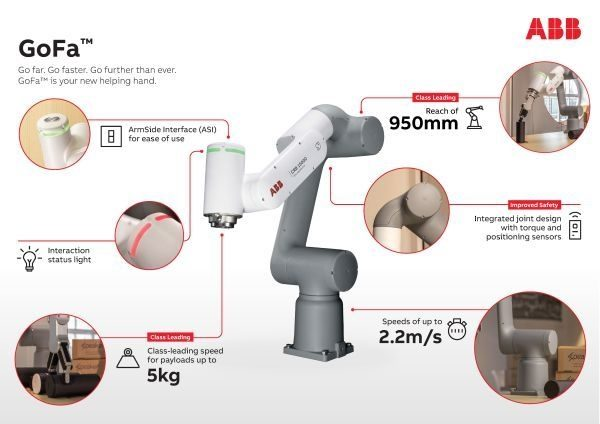

**b) Capacidad de carga.**

Tal como lo muestra la figura y revisando las especificaciones en el catálogo, la capacidad de carga (payload) de este robot es de 5kg. Hay que tener en cuenta el peso del efector final. Ya que esto hace que se reduzca el payload.

**c) Alcance vertical y horizontal. **

Tal como se muestra en el apartado e), el robot tiene un alcance vertical de 1216 mm y un alcance horizontal de 951 mm.

**d) Repetibilidad. **

**e) Gráfica(s) de espacio alcanzable.**

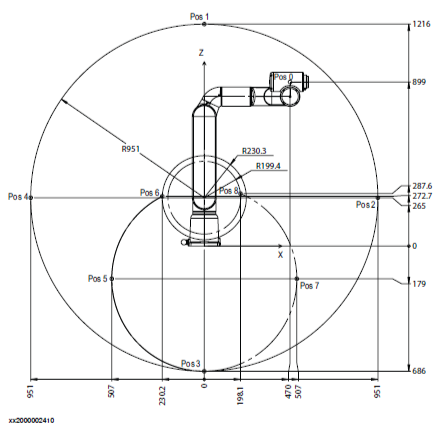

Para encontrar las zonas del espacio de trabajo del robot (en el plano XZ) , se configura el robot en 8 posiciones diferentes y se trazan las zonas, dichas posiciones están declaradas en la siguiente tabla:

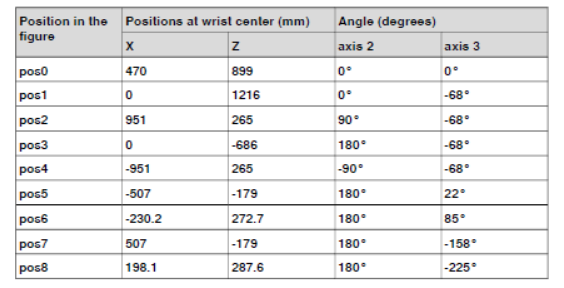

Para encontrar las zonas del espacio de trabajo del robot (en el plano XY), se configura el robot en las posiciones extremas y se trazan las zonas, dichas posiciones están declaradas en la siguiente tabla:

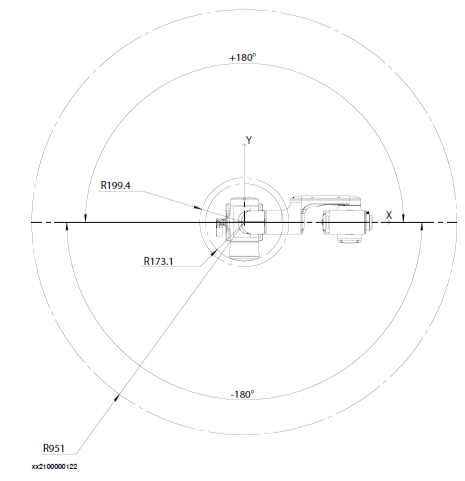

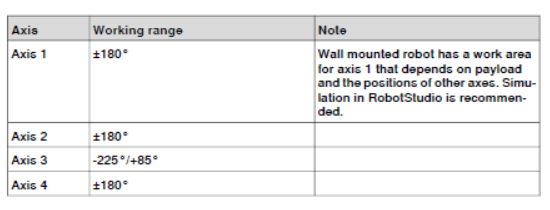

** f ) Tabla de parámetros DH.**

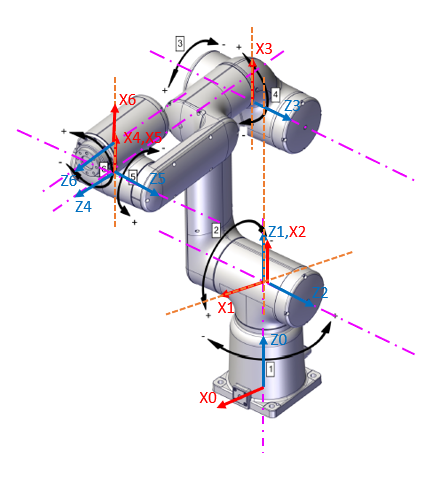

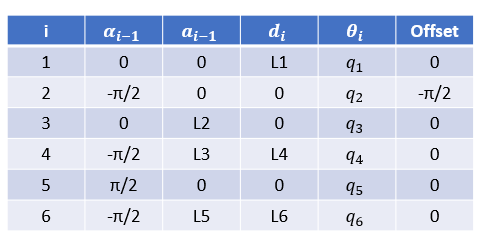

** g) Qué software utiliza el fabricante para diseño de celdas o programación. **

**h) ¿Qué otras características tiene? (Grado de protección IP, colaborativo, normas de seguridad etc.) **

**i) Haga un análisis del diagrama de la capacidad de carga.**

En la imagen a continuación, se puede observar el diagrama de carga para el efector final en posición vertical (muñeca vertical) hacia arriba, en donde ‘L’ equivale a la distancia en metros entre el centro de masa de la carga y efector final en el  plano XY y ‘Z’ equivale a la distancia en metros entre el centro de masa de la carga y el efector final en el eje Z. ‘L’ es igual a $L=\sqrt{X^2 +Y^2 }$, siendo ‘X’ el desplazamiento en el eje X y ‘Y’ el desplazamiento en el eje Y.

Teniendo en cuenta esas longitudes, se puede conocer mediante el diagrama la carga que se puede aplicar sobre la muñeca, verificando que esté dentro de la región de dicha carga.

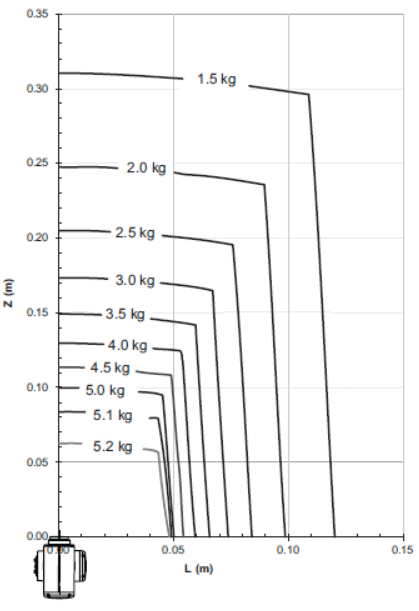

En la imagen a continuación, se puede observar el diagrama de carga para el efector final en posición vertical (muñeca vertical) hacia abajo, en donde ‘L’ equivale a la distancia en metros entre el centro de masa de la carga y efector final en el  plano XY y ‘Z’ equivale a la distancia en metros entre el centro de masa de la carga y el efector final en el eje Z. ‘L’ es igual a $L=\sqrt{X^2 +Y^2 }$, siendo ‘X’ el desplazamiento en el eje X y ‘Y’ el desplazamiento en el eje Y.

Teniendo en cuenta esas longitudes, se puede conocer mediante el diagrama la carga que se puede aplicar sobre la muñeca, verificando que esté dentro de la región de dicha carga.

Se puede deducir que se tiene una mayor capacidad de carga para la posición de la muñeca apuntando hacia abajo.

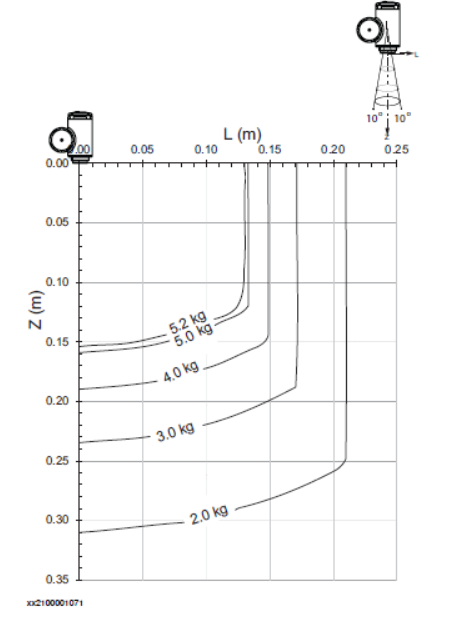

## 5. Iniciando

Haciendo uso de MATLAB® y los toolboxes construya un modelo del robot o utilice uno disponible en los toolboxes y que corresponda al robot asignado.

1. Realice el análisis geométrico del robot asignado a través de DH modificado y utilice las funciones de RVC para construir un modelo en alambres.  

clear all; close all;
syms theta_1 theta_2 theta_3 theta_4 theta_5 theta_6  
%q1=0; q2=0; q3=0; q4=0; q5=0; q6=0;
%Q=[q1,q2,q3,q4,q5,q6];
L1=0.265; L2=0.444; L3=0.110; L4=0.470; L5=0.080; L6=0.037;

L(1) = Link('revolute','alpha', 0,    'a', 0,   'd',L1,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(2) = Link('revolute','alpha', -pi/2,    'a', 0,   'd',0,   'offset', -pi/2,   'modified', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha', 0,    'a', L2,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(4) = Link('revolute','alpha', -pi/2,    'a', L3,   'd',L4,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(5) = Link('revolute','alpha', pi/2,    'a', 0,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha', -pi/2,    'a', L5,   'd',L6,   'offset', 0,   'modified', 'qlim',[-pi pi]);
%plot_options = {'workspace',[-2 2 -2 2 -2 2],'scale',0.05, 'view',[140 20]};
Robot_ABB = SerialLink(L,'name','ABB CRB 15000');
%figure()
Robot_ABB.plot([0,0,0,0,0,0],'workspace',[-0.5 0.5 -0.5 0.5 -0.1 1],'scale',0.5,'noa', 'view',[140 20])

T_01=L(1).A(theta_1)

$$T\_01 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & 0\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & 0\\ 0 & 0 & 1 & \frac{53}{200}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_12=L(1).A(theta_2)

$$T\_12 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & 0\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & 0\\ 0 & 0 & 1 & \frac{53}{200}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_23=L(1).A(theta_3)

$$T\_23 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & 0\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & 0\\ 0 & 0 & 1 & \frac{53}{200}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_34=L(1).A(theta_4)

$$T\_34 = \left(\begin{array}{cccc} \cos\left(\theta_{4}\right) & -\sin\left(\theta_{4}\right) & 0 & 0\\ \sin\left(\theta_{4}\right) & \cos\left(\theta_{4}\right) & 0 & 0\\ 0 & 0 & 1 & \frac{53}{200}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_45=L(1).A(theta_5)

$$T\_45 = \left(\begin{array}{cccc} \cos\left(\theta_{5}\right) & -\sin\left(\theta_{5}\right) & 0 & 0\\ \sin\left(\theta_{5}\right) & \cos\left(\theta_{5}\right) & 0 & 0\\ 0 & 0 & 1 & \frac{53}{200}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_56=L(1).A(theta_6)

$$T\_56 = \left(\begin{array}{cccc} \cos\left(\theta_{6}\right) & -\sin\left(\theta_{6}\right) & 0 & 0\\ \sin\left(\theta_{6}\right) & \cos\left(\theta_{6}\right) & 0 & 0\\ 0 & 0 & 1 & \frac{53}{200}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Robot_ABB.fkine([0 0 0 0 0 0]);

2. Considerando el robot asignado, construya el modelo del robot utilizando RST.  

clear all; close all;
q1=0; q2=0; q3=0; q4=0; q5=0; q6=0;
Q=[q1,q2,q3,q4,q5,q6];
L1=0.265; L2=0.444; L3=0.110; L4=0.470; L5=0.080; L6=0.037;

L(1) = Link('revolute','alpha', 0,    'a', 0,   'd',L1,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(2) = Link('revolute','alpha', -pi/2,    'a', 0,   'd',0,   'offset', -pi/2,   'modified', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha', 0,    'a', L2,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(4) = Link('revolute','alpha', -pi/2,    'a', L3,   'd',L4,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(5) = Link('revolute','alpha', pi/2,    'a', 0,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha', -pi/2,    'a', L5,   'd',L6,   'offset', 0,   'modified', 'qlim',[-pi pi]);

plot_options = {'workspace',[-10 10 -10 10 -10 10],'scale',0.05, 'view',[130 20]};
Robot_ABB = SerialLink(L,'name','ABB CRB 15000','plotopt',plot_options);

T_06=Robot_ABB.fkine(Q)

T_06 =     0.0000    0.0000    1.0000    0.5070
   -0.0000   -1.0000    0.0000   -0.0000
    1.0000   -0.0000   -0.0000    0.8990
         0         0         0    1.0000


## 6. Modelo Geométrico Directo

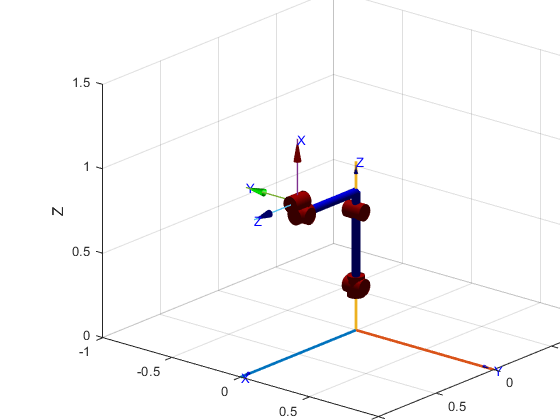

clear all; close all;
q1=0; q2=0; q3=0; q4=0; q5=0; q6=0;
Q=[q1,q2,q3,q4,q5,q6];
L1=0.265; L2=0.444; L3=0.110; L4=0.470; L5=0.080; L6=0.037;

L(1) = Link('revolute','alpha', 0,    'a', 0,   'd',L1,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(2) = Link('revolute','alpha', -pi/2,    'a', 0,   'd',0,   'offset', -pi/2,   'modified', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha', 0,    'a', L2,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(4) = Link('revolute','alpha', -pi/2,    'a', L3,   'd',L4,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(5) = Link('revolute','alpha', pi/2,    'a', 0,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha', -pi/2,    'a', L5,   'd',L6,   'offset', 0,   'modified', 'qlim',[-pi pi]);

plot_options = {'workspace',[-10 10 -10 10 -10 10],'scale',0.05, 'view',[90 20]};
Robot_ABB = SerialLink(L,'name','ABB CRB 15000','plotopt',plot_options);
figure;
hold on;
trplot(eye(4), 'width',2,'arrow');
axis([-1 1 -1 1 0 1.5]);
Robot_ABB.teach([0 0 0 0 0 0]);

%Robot_ABB.teach([0 0 -pi/2 0 0 0]);
%Robot_ABB.teach([0 pi/2 -pi/2 0 -pi/2 0]);
